## **Limpiar variables**

 
clear

## Valores iniciales

**Posición del robot**

x = 0;
y = 0;
z = 0;
p_robot = [x; y; z];

**Orientación del robot**

phi = 0;    %Rotación en el eje X
theta = 0;  %Rotación en el eje Y
psi = 0;    %Rotación en el eje Z
ori_robot = deg2rad([phi; theta; psi]);
secuencia = "XYZ";

**Matriz de transformación homogenea inicial**

R_inicial = euler2rotMat(ori_robot,secuencia);
A0 = [R_inicial  p_robot
      zeros(1,3) 1];

**Crear estructura del robot en base a la tabla DH y los valores iniciales**

dh = readtable('datos\tabla_DH\robot1.csv');
robot = crear_robot(dh,A0);

**Trayectoria cartesiana del robot**

p = readtable("datos\trayectorias\cargar_trayectoria_1.csv");
n = length(p.x);
% R_puntos = zeros(3,3,n);
% for i = 1:n
%     euler_puntos = deg2rad([p.phi(i);p.theta(i);p.psi(i)]);
%     R_puntos(:,:,i) = euler2rotMat(euler_puntos,secuencia);
% end
pos_puntos = [p.x';p.y';p.z'];
% z_puntos = R_puntos(:,3,:);
 

## **Cinemática inversa de los puntos**

Se basa en el descenso del gradiente o jacobiano, donde a través de varias iteraciones y a una velocidad $\alpha$, se obtiene un valor objetivo reduciendo el error.

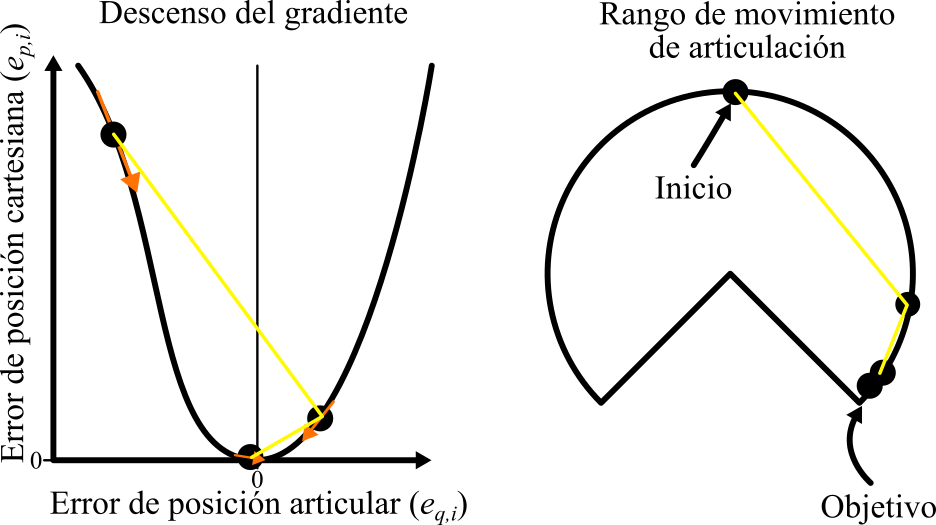

En caso de tener límites, a veces existen mínimos globales donde el descenso del gradiente no nos permitirá reducir más el error. Para solucionarlo, se usan varios candidatos que se distribuyen uniformemente en todo el rango de las articulacuiones y así al menos uno de ellos llegará al error objetivo.

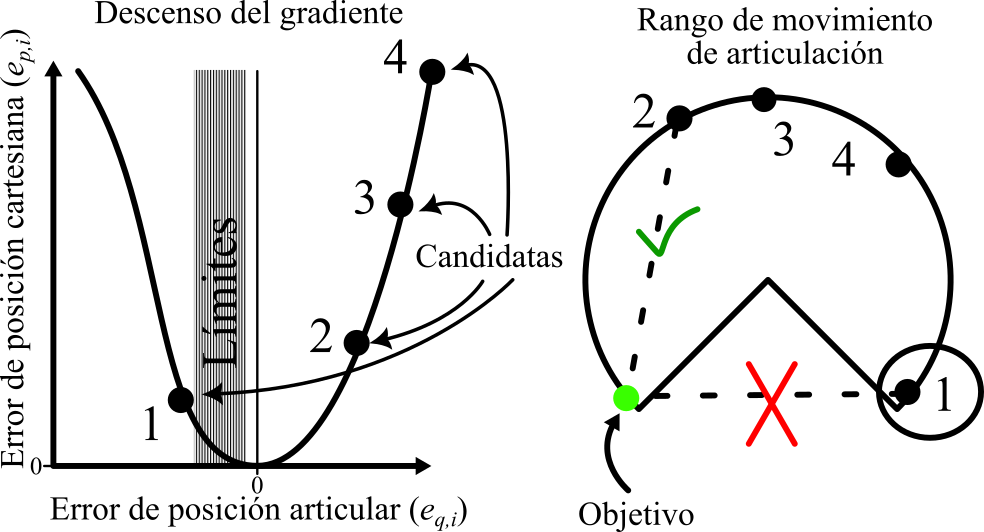

tol = 1e-6; % error máximo tolerado
max_iter = 100; % iteraciones del descenso del gradiente
alpha = 1.0;    % factor de corrección del descenso del gradiente
numSamples = 9; % Esto sirve para buscar diferentes puntos en caso de llegar a un mínimo local
q_sol = zeros(robot.NGDL,n);
p_sol = zeros(size(pos_puntos));
for i = 1:n
    [q_sol(:,i),p_sol(:,i)] = cinematica_inv(robot, pos_puntos(:,i), tol, max_iter, alpha, numSamples);
end

Solución alcanzada en muestra 1, iteraciones 4, error = 3.713825e-12
Solución alcanzada en muestra 1, iteraciones 4, error = 1.452969e-08


## **Trayectoria de punto articular a punto articular**

% Calcular la diferencia entre la configuración final y la inicial para cada junta
delta_q = abs(q_sol(:,2) - q_sol(:,1));
% Usar el valor más alto de los tiempos mínimos requeridos para cada junta,
% de forma que siempre sea un perfil triangular.
t_final = max(2 * delta_q ./ robot.dqMax);
% Muestras para graficar trayectoria
numSamples = 201;

[q, dq, ddq, t, pp] = trapveltraj(q_sol, numSamples, ...
                                            'Acceleration', robot.ddqMax, ...
                                            'EndTime', t_final);

## Cinemática directa

[posicion, vel_linear, acel_linear, orientacion, vel_angular, acel_angular] = cinematica_dir(robot,q,dq,ddq,t,secuencia);

## Animación

Si solo vas a imprimir la gráfica, debes usar 30 fps (la mitad de los que dice la gráfica).

close all
fps = 30;

t_animacion = 0:1/fps:t_final;
animSamples = length(t_animacion);

**Crear estructura gráfica del robot**

g = crear_grafica_robot();

**Generar el nombre del archivo con fecha y hora actual**

nombre_video = sprintf('resultados/animaciones/cinematica_directa_robot1_%s.avi', datestr(now, 'yyyy-mm-dd_HH-MM-SS'));

**Comenta las siguientes lineas si no quieres generar el video**

% videoObj = VideoWriter(nombre_video);
% videoObj.FrameRate = fps;
% open(videoObj);

**Generar animación**

q_anim = zeros(robot.NGDL,1);
for k = 1:length(t_animacion)
    for i = 1:robot.NGDL
        q_anim(i) = ppval(cell2mat(pp(i)),t_animacion(k));
    end
    robot = actualizar_robot_completo(robot, q_anim);
    g = dibujar_robot(g, robot);
    

**            Capturar el fotograma actual y escribirlo en el video (comenta si no quieres generar video)**

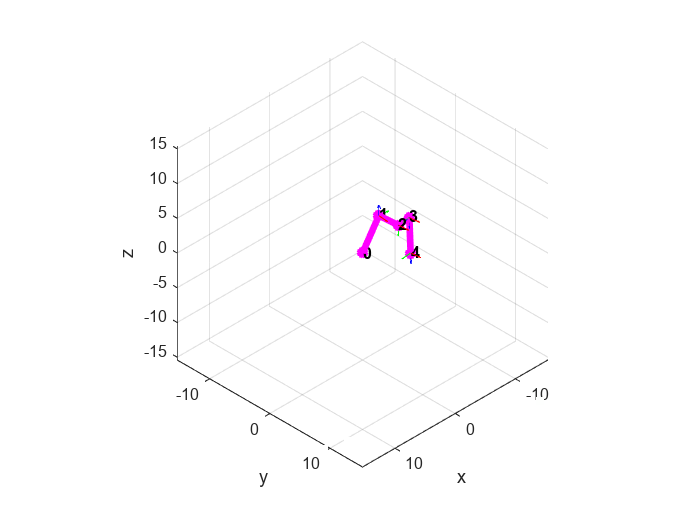

%     frame = getframe(gcf);
%     writeVideo(videoObj, frame);
end

## **Gráficas**

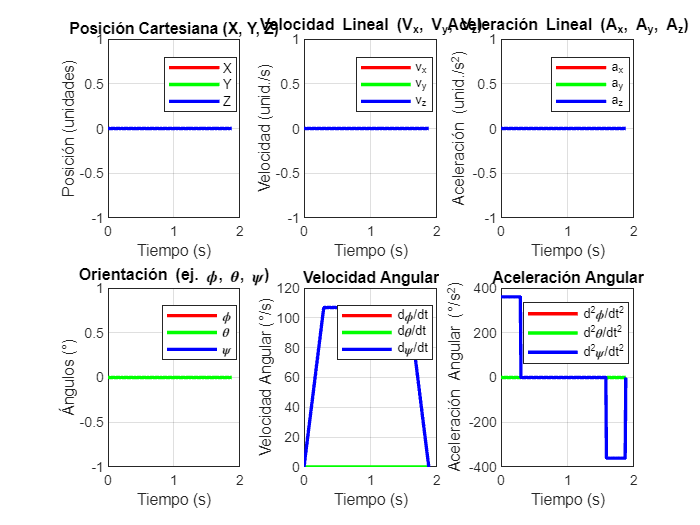

plotCartesian(t, posicion, vel_linear, acel_linear, orientacion, vel_angular, acel_angular)

**Cinemática articular**

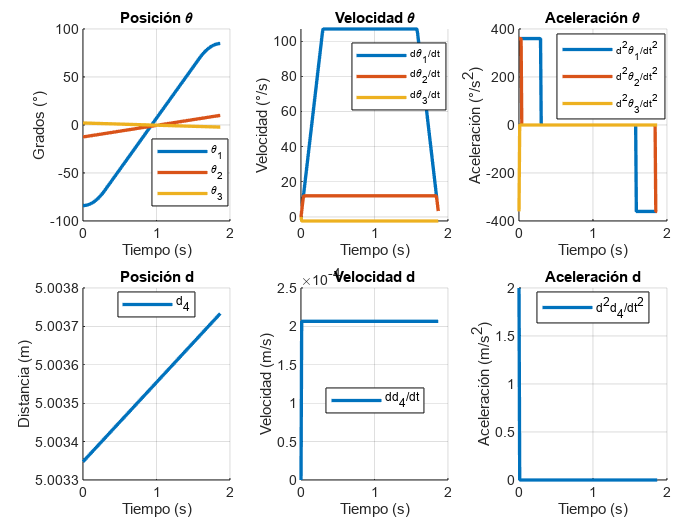

plotJoints(robot,t,q,dq,ddq)